%% CLOSED-LOOP CONTROL OF PATHOLOGICAL NEURAL OSCILLATIONS USING SIMULINK
%  Systems Simulations Lab Mini Project
%
%  Run this single script. It will:
%   1. Define all parameters (pushed to the base workspace for Simulink)
%   2. Calibrate the FitzHugh-Nagumo time scale so the limit cycle sits at 6 Hz
%   3. Design the 4th-order Butterworth 4-8 Hz band-pass filter
%   4. Build the Simulink model 'dbs_closed_loop.slx' programmatically
%   5. Simulate: (a) no stimulation, (b) open-loop DBS, (c) closed-loop DBS
%   6. Plot time responses, PSDs and stimulation-energy comparison
%
%  Requirements: MATLAB + Simulink + Signal Processing Toolbox (butter, pwelch)
%  Tested layout targets R2020b or later.
%
%  Signal flow:  Plant v(t) -> BPF(4-8Hz) -> moving RMS y(t) -> e = r-y
%                -> PID (anti-windup) u(t) -> 130 Hz biphasic pulses Istim -> Plant

clear; clc; close all;
mdl = 'dbs_closed_loop';

%% 1. PARAMETERS ---------------------------------------------------------
% --- FitzHugh-Nagumo (dimensionless form) ---
P.fhn_a   = 0.7;     P.fhn_b = 0.8;   P.fhn_tau = 12.5;
P.fhn_v0  = -1.2;    P.fhn_w0 = -0.6;
P.f_tremor = 6;      % Hz, target pathological frequency (inside 4-8 Hz band)

% --- Pathology / noise ---
P.Iext_on  = 0.5;    % excitability after onset (limit-cycle regime)
P.t_on     = 2;      % s, tremor onset time (healthy before this)
P.sigma    = 0.05;   % noise standard deviation (current units)
P.Tn       = 1e-3;   % noise sample time (s)

% --- Sampling / solver ---
P.Ts       = 1e-3;   % s, DSP sample time (fs = 1 kHz)
P.Tstep    = 1e-4;   % s, fixed solver step
P.Tstop    = 20;     % s
P.Tlog     = 1e-3;   % s, logging interval

% --- Biomarker extraction ---
P.band     = [4 8];  % Hz
P.Nwin     = 250;    % moving-RMS window length in samples (0.25 s)

% --- Controller (PID with clamping anti-windup) ---
P.Kp = 1.5;  P.Ki = 3;  P.Kd = 0.02;  P.Nd = 50;
P.uMax = 1.5;        % saturation: u in [-uMax, 0]  (cathodic/suppressive)

% --- Stimulation actuator (130 Hz charge-balanced biphasic) ---
% Pulse timing in whole solver steps (required by fixed-step Pulse Generator):
% period 77 steps x 0.1 ms = 7.7 ms -> 129.9 Hz ~ 130 Hz
P.stim_N      = 77;  % period (samples)
P.stim_pwN    = 15;  % width of EACH phase (samples) -> equal phases => charge-balanced
P.stim_delayN = 38;  % anodic phase starts ~half a period later (samples)
P.pulse_gain = 4;    % pulse amplitude scaling
P.stim_dc    = 0.7;  % share of command acting as mean-field (averaged) drive;
                     % reduced FHN cannot resolve HFS network effects, so this
                     % emulates the effective excitability shift. Set 0 for pure
                     % biphasic pulses.
P.ol_amp     = 0.8;  % open-loop (continuous) stimulation amplitude

% --- Scenario switches (changed per run) ---
P.cl_enable = 0;  P.ol_enable = 0;
P.r_ref = 0.05;   % small positive setpoint ~ just above the healthy noise floor of y;
                  % with r=0 the error can never turn positive, so the integrator
                  % could never release and stimulation would never throttle down

%% 2. CALIBRATE TIME-SCALE so oscillation frequency = f_tremor -------------
f_dim = @(t,x)[x(1)-x(1)^3/3-x(2)+P.Iext_on; ...
               (x(1)+P.fhn_a-P.fhn_b*x(2))/P.fhn_tau];
[tt,xx] = ode45(f_dim,[0 800],[P.fhn_v0;P.fhn_w0], ...
                odeset('RelTol',1e-8,'AbsTol',1e-10));
m  = tt > 300;  t2 = tt(m);  v2 = xx(m,1);
ix = find(v2(1:end-1) < 0 & v2(2:end) >= 0);
assert(numel(ix) >= 3, 'FHN did not enter a limit cycle - check Iext_on.');
tc = t2(ix) + (0 - v2(ix)).*(t2(ix+1)-t2(ix))./(v2(ix+1)-v2(ix));
Tdim = mean(diff(tc));
P.fhn_k = Tdim * P.f_tremor;          % t_real = t_dim / k
fprintf('Dimensionless period = %.2f -> time-scale k = %.1f (f = %.1f Hz)\n', ...
        Tdim, P.fhn_k, P.f_tremor);

Dimensionless period = 39.47 -> time-scale k = 236.8 (f = 6.0 Hz)



%% 3. DIGITAL BAND-PASS FILTER (4th-order Butterworth = butter(2,...)) -----
fs = 1/P.Ts;
[P.bpf_num, P.bpf_den] = tf_bandpass(P.band, fs);
P.rms_num = ones(1,P.Nwin)/P.Nwin;          % moving average (FIR) numerator
P.rms_den = [1 zeros(1,P.Nwin-1)];

% push everything to base workspace (blocks reference these names)
fn = fieldnames(P);
for i = 1:numel(fn), assignin('base', fn{i}, P.(fn{i})); end

%% 4. BUILD SIMULINK MODEL -------------------------------------------------
build_model(mdl);


%% 5. RUN THREE SCENARIOS --------------------------------------------------
scen = {'No stimulation', 0, 0; ...
        'Open-loop DBS',  0, 1; ...
        'Closed-loop DBS',1, 0};
R = struct();
for s = 1:size(scen,1)
    assignin('base','cl_enable',scen{s,2});
    assignin('base','ol_enable',scen{s,3});
    fprintf('Simulating: %s ...\n', scen{s,1});
    out = sim(mdl);
    R(s).name = scen{s,1};
    R(s).t  = out.tout;
    R(s).v  = out.v_log(:);
    R(s).y  = out.y_log(:);
    R(s).u  = out.u_log(:);
    R(s).I  = out.Istim_log(:);
end

Simulating: No stimulation ...
Simulating: Open-loop DBS ...
Simulating: Closed-loop DBS ...



%% 6. METRICS --------------------------------------------------------------
tl = (0:numel(R(1).v)-1)' * P.Tlog;         % logged time axis
win = tl > (P.t_on + 4);                    % steady-state window after onset
fprintf('\n%-18s %14s %18s %16s\n','Scenario','Mean tremor y','Stim energy (a.u.)','Mean |u|');


Scenario            Mean tremor y Stim energy (a.u.)         Mean |u|


for s = 1:numel(R)
    R(s).yMean  = mean(R(s).y(win));
    R(s).energy = sum(R(s).I.^2) * P.Tlog;
    R(s).uMean  = mean(abs(R(s).u(win)));
    fprintf('%-18s %14.4f %18.3f %16.4f\n', R(s).name, R(s).yMean, R(s).energy, R(s).uMean);
end

No stimulation             1.2190              0.000           0.0000
Open-loop DBS              0.0063             13.455           0.8000
Closed-loop DBS            0.0556              5.937           0.4890


red = 100*(1 - R(3).yMean/R(1).yMean);
sav = 100*(1 - R(3).energy/R(2).energy);
fprintf('\nClosed-loop tremor reduction : %.1f %%\n', red);


Closed-loop tremor reduction : 95.4 %


fprintf('Energy saving vs open-loop   : %.1f %%\n', sav);

Energy saving vs open-loop   : 55.9 %


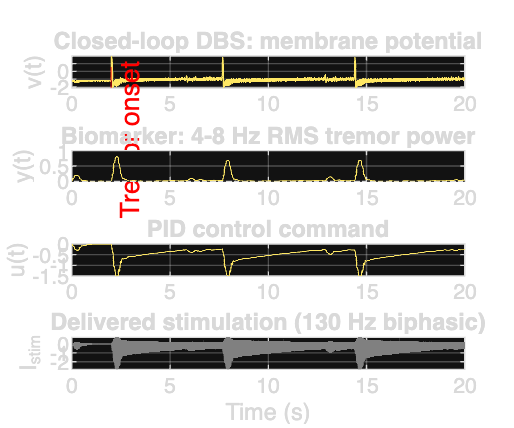


%% 7. PLOTS ----------------------------------------------------------------
cols = lines(3);

% Fig 1: closed-loop detail
figure('Name','Closed-loop response','Color','w','Position',[80 60 900 750]);
subplot(4,1,1); plot(tl,R(3).v,'Color',cols(3,:)); grid on;
ylabel('v(t)'); title('Closed-loop DBS: membrane potential');
xline(P.t_on,'r--','Tremor onset');
subplot(4,1,2); plot(tl,R(3).y,'Color',cols(3,:)); grid on; ylabel('y(t)');
title('Biomarker: 4-8 Hz RMS tremor power'); yline(0,'k:');
subplot(4,1,3); plot(tl,R(3).u,'Color',cols(3,:)); grid on; ylabel('u(t)');
title('PID control command');
subplot(4,1,4); plot(tl,R(3).I,'Color',[.5 .5 .5]); grid on;
ylabel('I_{stim}'); xlabel('Time (s)'); title('Delivered stimulation (130 Hz biphasic)');

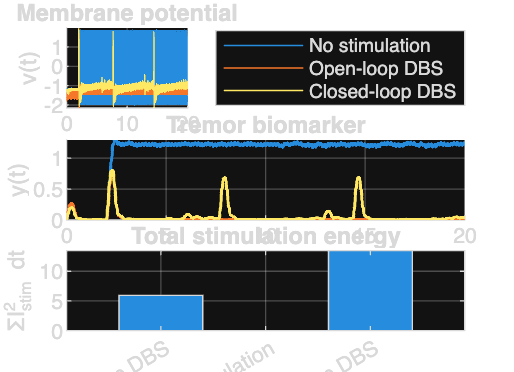


% Fig 2: scenario comparison
figure('Name','Scenario comparison','Color','w','Position',[120 80 900 650]);
subplot(3,1,1); hold on;
for s=1:3, plot(tl,R(s).v,'Color',cols(s,:)); end
grid on; ylabel('v(t)'); legend(R.name,'Location','eastoutside'); title('Membrane potential');
subplot(3,1,2); hold on;
for s=1:3, plot(tl,R(s).y,'Color',cols(s,:),'LineWidth',1.2); end
grid on; ylabel('y(t)'); title('Tremor biomarker');
subplot(3,1,3);
bar(categorical({R.name}), [R.energy]); ylabel('\SigmaI_{stim}^2 dt'); grid on;
title('Total stimulation energy');

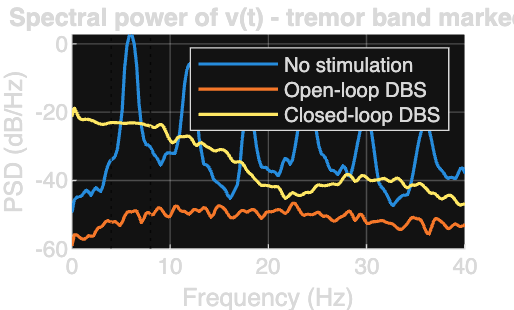


% Fig 3: PSD of membrane potential after onset
figure('Name','PSD','Color','w'); hold on;
seg = tl > (P.t_on + 4);
for s=1:3
    [pxx,f] = pwelch(R(s).v(seg)-mean(R(s).v(seg)), hann(2048), 1024, 4096, fs);
    plot(f, 10*log10(pxx+eps), 'Color', cols(s,:), 'LineWidth',1.2);
end
xlim([0 40]); grid on; xline(P.band(1),'k:'); xline(P.band(2),'k:');
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)'); legend(R.name);
title('Spectral power of v(t) - tremor band marked');


open_system(mdl);

%% ========================= LOCAL FUNCTIONS ==============================
function [num,den] = tf_bandpass(band, fs)
    [z,p,k] = butter(2, band/(fs/2), 'bandpass');   % 2*2 = 4th order
    [sos,g] = zp2sos(z,p,k);
    num = 1; den = 1;
    for i = 1:size(sos,1)
        num = conv(num, sos(i,1:3));
        den = conv(den, sos(i,4:6));
    end
    num = num*g;
end

function build_model(mdl)
    if bdIsLoaded(mdl), close_system(mdl,0); end
    new_system(mdl); open_system(mdl);

    S = 'simulink/';
    B = @(lib,name,pos,varargin) add_block([S lib], [mdl '/' name], ...
            'Position',pos, varargin{:});
    pos = @(x,y,w,h) [x y x+w y+h];

    % ---------- Plant (FitzHugh-Nagumo) ----------
    B('Sources/Step','Iext',pos(30,40,50,30),'Time','t_on','Before','0','After','Iext_on');
    B('Sources/Band-Limited White Noise','Noise',pos(30,100,50,30), ...
        'Cov','sigma^2*Tn','Ts','Tn','seed','[23341]');
    B('Math Operations/Sum','Sum_I',pos(130,60,30,70),'Inputs','+++');
    B('Signal Routing/Mux','Mux3',pos(210,60,6,70),'Inputs','3');
    B('User-Defined Functions/Fcn','Fcn_v',pos(260,75,200,30), ...
        'Expr','fhn_k*(u(1)-u(1)^3/3-u(2)+u(3))');
    B('Continuous/Integrator','Int_v',pos(500,75,30,30),'InitialCondition','fhn_v0');
    B('Signal Routing/Mux','Mux2',pos(210,180,6,50),'Inputs','2');
    B('User-Defined Functions/Fcn','Fcn_w',pos(260,185,200,30), ...
        'Expr','fhn_k*(u(1)+fhn_a-fhn_b*u(2))/fhn_tau');
    B('Continuous/Integrator','Int_w',pos(500,185,30,30),'InitialCondition','fhn_w0');

    add_line(mdl,'Iext/1','Sum_I/1');
    add_line(mdl,'Noise/1','Sum_I/3');
    add_line(mdl,'Sum_I/1','Mux3/3');
    add_line(mdl,'Mux3/1','Fcn_v/1');  add_line(mdl,'Fcn_v/1','Int_v/1');
    add_line(mdl,'Int_v/1','Mux3/1');  add_line(mdl,'Int_v/1','Mux2/1');
    add_line(mdl,'Int_w/1','Mux3/2');  add_line(mdl,'Int_w/1','Mux2/2');
    add_line(mdl,'Mux2/1','Fcn_w/1');  add_line(mdl,'Fcn_w/1','Int_w/1');

    % ---------- Signal conditioning / biomarker ----------
    B('Discrete/Discrete Transfer Fcn','BPF_4_8Hz',pos(620,70,110,40), ...
        'Numerator','bpf_num','Denominator','bpf_den','SampleTime','Ts');
    B('Math Operations/Math Function','Square',pos(770,75,40,30),'Operator','square');
    B('Discrete/Discrete Transfer Fcn','MovingMean',pos(850,70,110,40), ...
        'Numerator','rms_num','Denominator','rms_den','SampleTime','Ts');
    B('Discontinuities/Saturation','NonNeg',pos(1000,75,40,30), ...
        'UpperLimit','inf','LowerLimit','0');
    B('Math Operations/Math Function','Sqrt',pos(1080,75,40,30),'Operator','sqrt');

    add_line(mdl,'Int_v/1','BPF_4_8Hz/1');
    add_line(mdl,'BPF_4_8Hz/1','Square/1');
    add_line(mdl,'Square/1','MovingMean/1');
    add_line(mdl,'MovingMean/1','NonNeg/1');
    add_line(mdl,'NonNeg/1','Sqrt/1');

    % ---------- Error detector + PID ----------
    B('Sources/Constant','Ref',pos(620,200,50,30),'Value','r_ref');
    B('Math Operations/Sum','Sum_err',pos(720,200,30,50),'Inputs','+-');
    B('Continuous/PID Controller','PID',pos(800,200,70,50), ...
        'Controller','PID','P','Kp','I','Ki','D','Kd','N','Nd', ...
        'LimitOutput','on','UpperSaturationLimit','0', ...
        'LowerSaturationLimit','-uMax');
    try, set_param([mdl '/PID'],'AntiWindupMode','clamping'); catch, end
    B('Math Operations/Gain','CL_gain',pos(910,205,40,40),'Gain','cl_enable');
    B('Sources/Constant','OL_const',pos(880,270,60,30),'Value','-ol_amp*ol_enable');
    B('Math Operations/Sum','Sum_u',pos(990,215,30,50),'Inputs','++');

    add_line(mdl,'Ref/1','Sum_err/1');
    add_line(mdl,'Sqrt/1','Sum_err/2','autorouting','on');
    add_line(mdl,'Sum_err/1','PID/1');
    add_line(mdl,'PID/1','CL_gain/1');
    add_line(mdl,'CL_gain/1','Sum_u/1');
    add_line(mdl,'OL_const/1','Sum_u/2');

    % ---------- Stimulation actuator ----------
    B('Sources/Pulse Generator','Pulse_cathodic',pos(620,340,60,30), ...
        'PulseType','Sample based','SampleTime','Tstep', ...
        'Amplitude','1','Period','stim_N','PulseWidth','stim_pwN','PhaseDelay','0');
    B('Sources/Pulse Generator','Pulse_anodic',pos(620,390,60,30), ...
        'PulseType','Sample based','SampleTime','Tstep', ...
        'Amplitude','1','Period','stim_N','PulseWidth','stim_pwN','PhaseDelay','stim_delayN');
    B('Math Operations/Sum','Sum_bp',pos(730,355,30,50),'Inputs','+-');
    B('Math Operations/Gain','Pulse_gain',pos(790,360,60,40),'Gain','(1-stim_dc)*pulse_gain');
    B('Sources/Constant','Dc_part',pos(790,420,60,30),'Value','stim_dc');
    B('Math Operations/Sum','Sum_mix',pos(890,370,30,50),'Inputs','++');
    B('Math Operations/Product','Mult',pos(980,340,30,50));

    add_line(mdl,'Pulse_cathodic/1','Sum_bp/1');
    add_line(mdl,'Pulse_anodic/1','Sum_bp/2');
    add_line(mdl,'Sum_bp/1','Pulse_gain/1');
    add_line(mdl,'Pulse_gain/1','Sum_mix/1');
    add_line(mdl,'Dc_part/1','Sum_mix/2');
    add_line(mdl,'Sum_mix/1','Mult/2');
    add_line(mdl,'Sum_u/1','Mult/1');
    add_line(mdl,'Mult/1','Sum_I/2','autorouting','on');   % close the loop

    % ---------- Logging & scope ----------
    logs = {'v_log','Int_v'; 'y_log','Sqrt'; 'u_log','Sum_u'; 'Istim_log','Mult'};
    for i = 1:size(logs,1)
        nm = ['TW_' logs{i,1}];
        B('Sinks/To Workspace',nm,pos(1180,40+45*(i-1),70,30), ...
            'VariableName',logs{i,1},'SaveFormat','Array','SampleTime','Tlog');
        add_line(mdl,[logs{i,2} '/1'],[nm '/1'],'autorouting','on');
    end
    B('Sinks/Scope','Scope',pos(1180,260,50,90),'NumInputPorts','4');
    add_line(mdl,'Int_v/1','Scope/1','autorouting','on');
    add_line(mdl,'Sqrt/1','Scope/2','autorouting','on');
    add_line(mdl,'Sum_u/1','Scope/3','autorouting','on');
    add_line(mdl,'Mult/1','Scope/4','autorouting','on');

    % ---------- Solver ----------
    set_param(mdl,'SolverType','Fixed-step','Solver','ode4', ...
        'FixedStep','Tstep','StopTime','Tstop', ...
        'ReturnWorkspaceOutputs','on','SaveTime','on');

    % ---------- Group into the four subsystems from the synopsis ----------
    groups = { ...
      'Neural_Plant_FHN',   {'Iext','Noise','Sum_I','Mux3','Fcn_v','Int_v','Mux2','Fcn_w','Int_w'}; ...
      'Biomarker_Extraction',{'BPF_4_8Hz','Square','MovingMean','NonNeg','Sqrt'}; ...
      'PID_Controller',     {'Ref','Sum_err','PID','CL_gain','OL_const','Sum_u'}; ...
      'Stimulation_Actuator',{'Pulse_cathodic','Pulse_anodic','Sum_bp','Pulse_gain','Dc_part','Sum_mix','Mult'}};
    try
        for g = 1:size(groups,1)
            h = cellfun(@(n) get_param([mdl '/' n],'Handle'), groups{g,2});
            Simulink.BlockDiagram.createSubsystem(h,'Name',groups{g,1});
        end
    catch ME
        warning('Subsystem grouping skipped (%s). Flat model still works.', ME.message);
    end

    save_system(mdl);
end